# 2016-2017

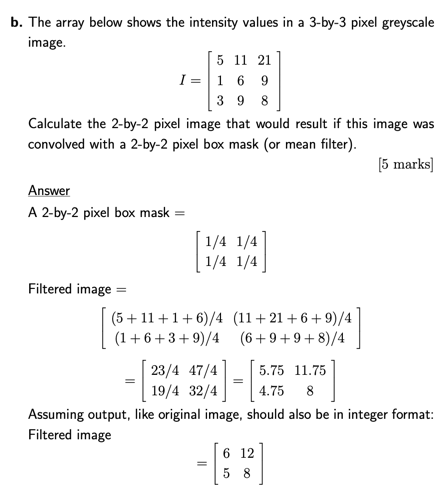

% Calculate the 2-by-2 pixel image that would result if this image was convolved with a 2-by-2 pixel box mask (or mean filter).
I = [5 11 21
     1 6 9
     3 9 8];

box_size = 2;

box = ones(box_size) / (box_size*box_size);
filtered_image = conv2(I,box,"valid")

filtered_image =     5.7500   11.7500
    4.7500    8.0000


% filtered_image = round(conv2(I,box,"valid"),0)

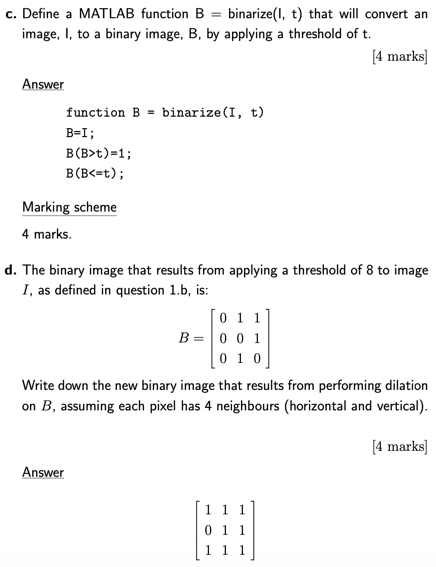

% Write down the new binary image that results from performing dilation on B, assuming each pixel has 4 neighbours (horizontal and vertical).
B = [0 1 1
     0 0 1
     0 1 0];

% 4 neighbours
SE_4 = strel("diamond", 1);
imdilate(B, SE_4)

ans =      1     1     1
     0     1     1
     1     1     1


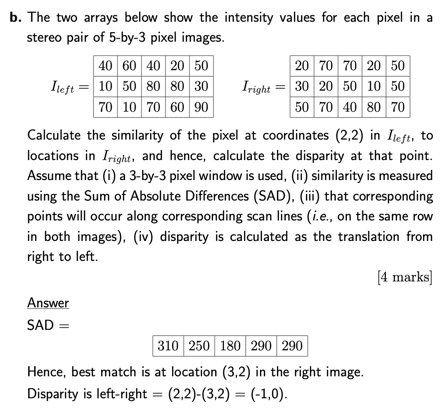

% Calculate the similarity of the pixel at coordinates (2,2) in Ileft, to locations in Iright, and hence, calculate the disparity at that point. Assume that (i) a 3-by-3 pixel window is used, (ii) similarity is measured using the Sum of Absolute Differences (SAD), (iii) that corresponding points will occur along corresponding scan lines (i.e., on the same row in both images), (iv) disparity is calculated as the translation from right to left.
coordinate = [2 2];

I_left_2_2 = [40 60 40
              10 50 80
              70 10 70];

I_right = [0 20 70 70 20 50 0
           0 30 20 50 10 50 0
           0 50 70 40 80 70 0];

SAD = NaN([3 5]);
for j = 2:6
    SAD(2, j-1) = sum_matrix(abs(I_left_2_2 - I_right(:,j-1:j+1)));
end

SAD

SAD =    NaN   NaN   NaN   NaN   NaN
   310   250   180   290   290
   NaN   NaN   NaN   NaN   NaN


% Minimum
best_match_at_location = img_find_min(SAD)

best_match_at_location =      3     2



disparity = coordinate - best_match_at_location

disparity =     -1     0


# 2017-2018

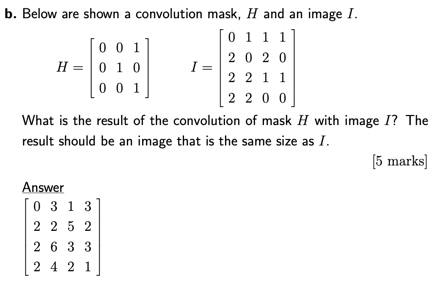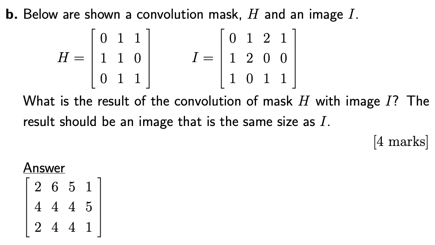

% Below are shown a convolution mask, H and an image I. What is the result of the convolution of mask H with image I? The result should be an image that is the same size as I.
H = [0 1 1
     1 1 0
     0 1 1];

I = [0 1 2 1
     1 2 0 0
     1 0 1 1];

conv2(I,H,"same")

ans =      2     6     5     1
     4     4     4     5
     2     4     4     1


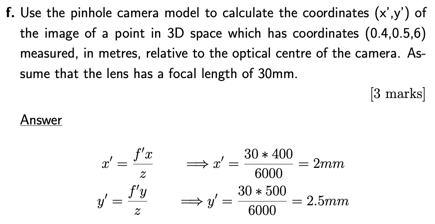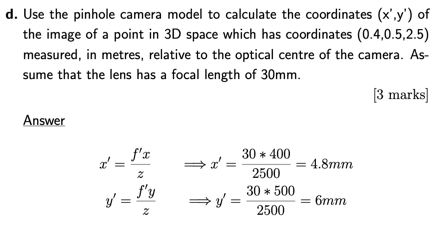

% Use the pinhole camera model to calculate the coordinates (x’,y’) of the image of a point in 3D space which has coordinates (0.4,0.5,6) measured, in metres, relative to the optical centre of the camera. As- sume that the lens has a focal length of 30mm.
point_3D = [0.4 0.5 2.5] * 1000; % m -> mm
focal_length = 30;

x = focal_length * point_3D(1) / point_3D(3)

x = 4.8000

y = focal_length * point_3D(2) / point_3D(3)

y = 6

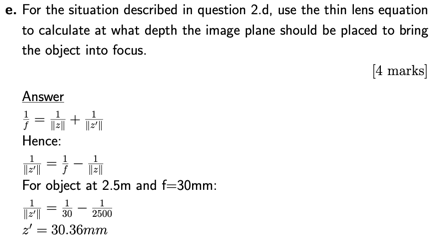

% For the situation described in question 2.d, use the thin lens equation to calculate at what depth the image plane should be placed to bring the object into focus.
z = 1 / (1 / focal_length - 1 / point_3D(3))

z = 30.3644

# 2018-2019

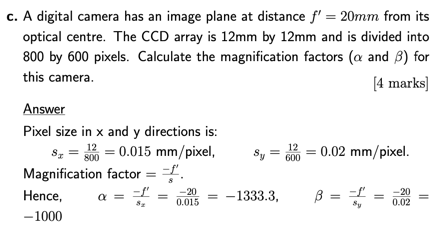

% A digital camera has an image plane at distance f′ = 20mm from its optical centre. The CCD array is 12mm by 12mm and is divided into 800 by 600 pixels. Calculate the magnification factors (α and β) for this camera.
f = 20;
CCD = [12 12];
divided = [800 600];

s_x = CCD(1) / divided(1);
s_y = CCD(2) / divided(2);

alpha = -f / s_x

alpha = -1.3333e+03

beta = -f / s_y

beta = -1000

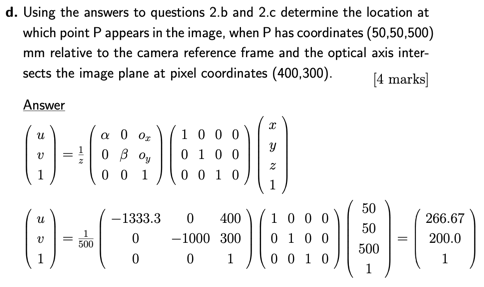

% Using the answers to questions 2.b and 2.c determine the location at which point P appears in the image, when P has coordinates (50,50,500) mm relative to the camera reference frame and the optical axis inter- sects the image plane at pixel coordinates (400,300).
principal_point = [400 300];
x = alpha;
y = beta;
point = [50 50 500];

location_in_img(x,y,principal_point,point)

ans =   266.6667
  200.0000
    1.0000


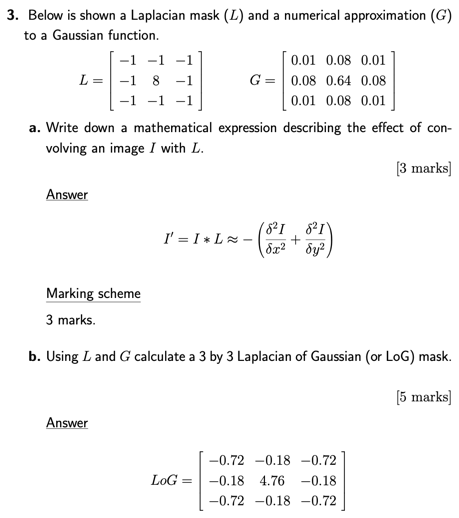

% Below is shown a Laplacian mask(L) and a numerical approximation(G) to a Gaussian function b. Using L and G calculate a 3 by 3 Laplacian of Gaussian (or LoG) mask
L = [-1 -1 -1
     -1 8 -1
     -1 -1 -1];

G = [0.01 0.08 0.01
     0.08 0.64 0.08
     0.01 0.08 0.01];

LoG = conv2(L,G,"same")

LoG =    -0.7200   -0.1800   -0.7200
   -0.1800    4.7600   -0.1800
   -0.7200   -0.1800   -0.7200


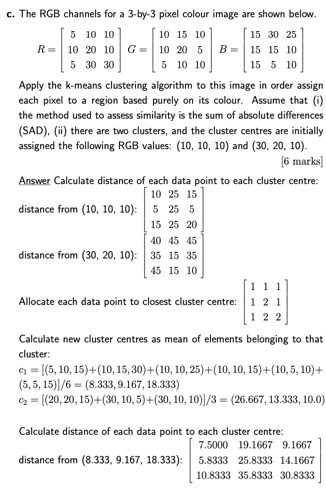

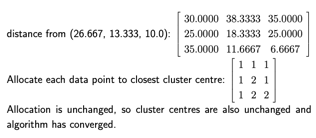

% Apply the k-means clustering algorithm to this image in order assign each pixel to a region based purely on its colour. Assume that (i) the method used to assess similarity is the sum of absolute differences (SAD), (ii) there are two clusters, and the cluster centres are initially assigned the following RGB values: (10, 10, 10) and (30, 20, 10).
R = [5 10 10
     10 20 10
     5 30 30];

G = [10 15 10
     10 20 5
     5 10 10];

B = [15 30 25
     15 15 10
     15 5 10];


c1 = [10 10 10];

c2 = [30 20 10];

% First k-means
distance_from_c1 = cal_distance(R,G,B,c1);
distance_from_c2 = cal_distance(R,G,B,c2);
closest_cluster_center = distance_from_c1 > distance_from_c2

closest_cluster_center = 3×3 logical array
   0   0   0
   0   1   0
   0   1   1



% Second k-means
[new_c1, new_c2] = cal_new_center(R,G,B,closest_cluster_center)

new_c1 =     8.3333    9.1667   18.3333


new_c2 =    26.6667   13.3333   10.0000


distance_from_new_c1 = cal_distance(R,G,B,new_c1)

distance_from_new_c1 =     7.5000   19.1667    9.1667
    5.8333   25.8333   14.1667
   10.8333   35.8333   30.8333


distance_from_new_c2 = cal_distance(R,G,B,new_c2)

distance_from_new_c2 =    30.0000   38.3333   35.0000
   25.0000   18.3333   25.0000
   35.0000   11.6667    6.6667


new_closest_cluster_center = distance_from_new_c1 > distance_from_new_c2

new_closest_cluster_center = 3×3 logical array
   0   0   0
   0   1   0
   0   1   1


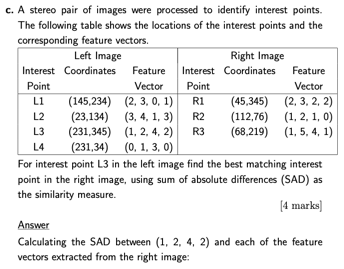

L3 = [1,2,4,2];
R1 = [2,3,2,2];
R2 = [1,2,1,0];
R3 = [1,5,4,1];

R1 = sum_matrix(abs(R1-L3))

R1 = 4

R2 = sum_matrix(abs(R2-L3))

R2 = 5

R3 = sum_matrix(abs(R3-L3))

R3 = 4

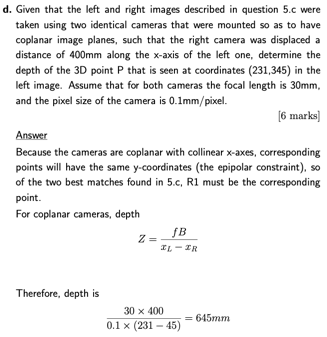

% Given that the left and right images described in question 5.c were taken using two identical cameras that were mounted so as to have coplanar image planes, such that the right camera was displaced a distance of 400mm along the x-axis of the left one, determine the depth of the 3D point P that is seen at coordinates (231,345) in the left image. Assume that for both cameras the focal length is 30mm, and the pixel size of the camera is 0.1mm/pixel.
R1_coordinate = [45, 345];
focal_length = 30;
camera_distance = 400;
point = [231,345];
pixel_size = 0.1;

Z = (focal_length * camera_distance) / (pixel_size * (point(1) - R1_coordinate(1)))

Z = 645.1613

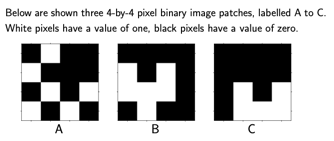

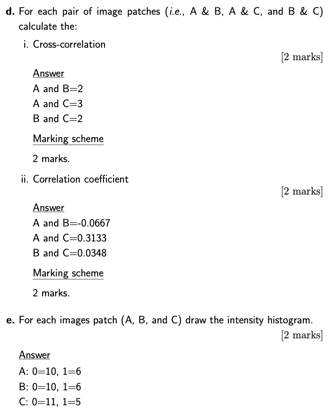

% Below are shown three 4-by-4 pixel binary image patches, labelled A to C. White pixels have a value of one, black pixels have a value of zero. A number of standard metrics can be used to compare two image patches. Write down the formulae for comparing two patches, A and B, using: i. cross-correlation ii. sum of absolute differences iii. correlation coefficient
A = [0 1 0 0
     1 0 0 0
     0 1 0 1
     1 0 1 0];

B = [0 0 0 0
     1 0 1 0
     1 1 1 0
     0 1 0 0];

C = [0 0 0 0
     0 0 0 0
     0 1 0 1
     0 1 1 1];

% Cross-correlation
A_180 = rot90(A, 90);
B_180 = rot90(B, 90);
C_180 = rot90(C, 90);

A_B = conv2(A, B_180, "valid")

A_B = 2

A_C = conv2(A, C_180, "valid")

A_C = 3

B_C = conv2(B, C_180, "valid")

B_C = 2


% Correlation coefficient
A_B = corr2(A, B)

A_B = -0.0667

A_C = corr2(A, C)

A_C = 0.3133

B_C = corr2(B, C)

B_C = 0.0348


% Intensity histogram
[A_zero, A_one] = intensity_histogram(A)

A_zero = 10

A_one = 6

[B_zero, B_one] = intensity_histogram(B)

B_zero = 10

B_one = 6

[C_zero, C_one] = intensity_histogram(C)

C_zero = 11

C_one = 5

# 2019-2020

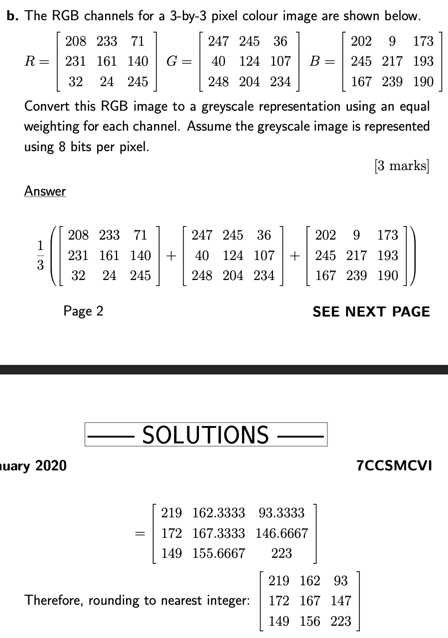

% The RGB channels for a 3-by-3 pixel colour image are shown below. Convert this RGB image to a greyscale representation using an equal weighting for each channel. Assume the greyscale image is represented using 8 bits per pixel.
R = [208 233 71
     231 161 140
     32 34 245];

G = [247 245 36
     40 124 107
     248 204 234];

B = [202 9 173
     245 217 193
     167 239 190];

img(:,:,1) = R;
img(:,:,2) = G;
img(:,:,3) = B;

% 8bit
I_gray_8 = mean(img,3);
nearest_integer = round(I_gray_8, 0)

nearest_integer =    219   162    93
   172   167   147
   149   159   223


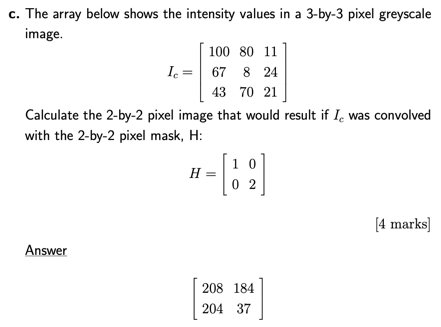

% The array below shows the intensity values in a 3-by-3 pixel greyscale image. Calculate the 2-by-2 pixel image that would result if Ic was convolved with the 2-by-2 pixel mask, H:. 
Ic = [100 80 11
      67 8 24
      43 70 21];

H = [1 0
     0 2];

conv2(H,Ic,"same")

ans =    208   184
   204    37


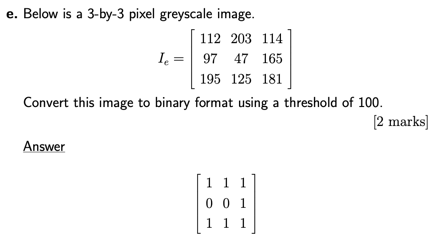

% Below is a 3-by-3 pixel greyscale image. Convert this image to binary format using a threshold of 100.
Ie = [112 203 114
      97 47 165
      195 125 181];

th = 100;

binary = ones(3);
for i = 1:3
    for j = 1:3
        if Ie(i,j) < th
            binary(i,j) = 0;
        end
    end
end

binary

binary =      1     1     1
     0     0     1
     1     1     1


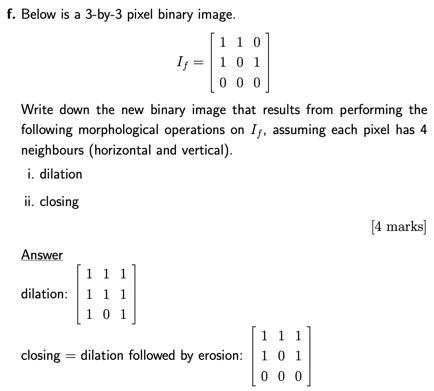

% Write down the new binary image that results from performing the following morphological operations on If, assuming each pixel has 4 neighbours (horizontal and vertical). i. dilation ii. closing
Ij = [1 1 0
      1 0 1
      0 0 0];

% 4 neighbours
SE_4 = strel("diamond", 1);
dilation = imdilate(Ij , SE_4)

dilation =      1     1     1
     1     1     1
     1     0     1


closing = imerode(dilation, SE_4)

closing =      1     1     1
     1     0     1
     0     0     0


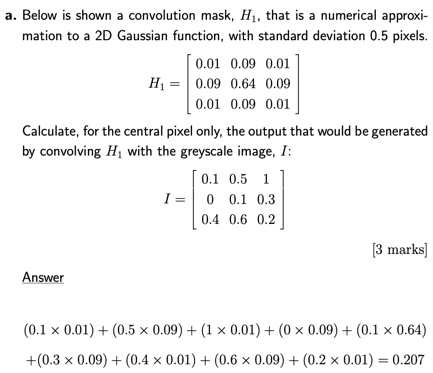

% Below is shown a convolution mask, H1, that is a numerical approximation to a 2D Gaussian function, with standard deviation 0.5 pixels. Calculate, for the central pixel only, the output that would be generated by convolving H1 with the greyscale image, I:
std = 0.5;

H1 = gaussian2D(std);

I = [0.1 0.5 1
     0 0.1 0.3
     0.4 0.6 0.2];

conv2(H1,I,"valid")

ans = 0.2070

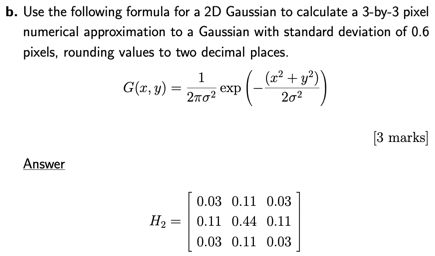

% Use the following formula for a 2D Gaussian to calculate a 3-by-3 pixel numerical approximation to a Gaussian with standard deviation of 0.6 pixels, rounding values to two decimal places.
std = 0.6;
H2 = gaussian2D(std)

H2 =     0.0300    0.1100    0.0300
    0.1100    0.4400    0.1100
    0.0300    0.1100    0.0300


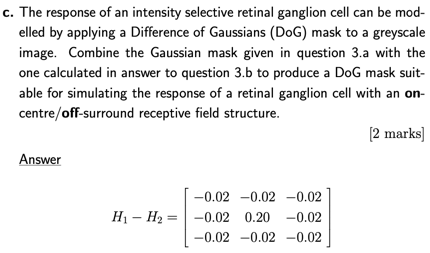

% The response of an intensity selective retinal ganglion cell can be mod- elled by applying a Difference of Gaussians (DoG) mask to a greyscale image. Combine the Gaussian mask given in question 3.a with the one calculated in answer to question 3.b to produce a DoG mask suit- able for simulating the response of a retinal ganglion cell with an on- centre/off-surround receptive field structure.
H2 - H1

ans =     0.0200    0.0200    0.0200
    0.0200   -0.2000    0.0200
    0.0200    0.0200    0.0200


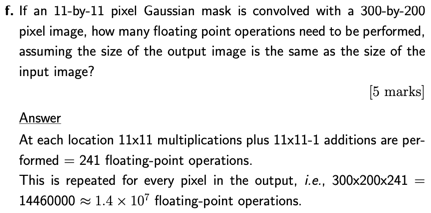

% If an 11-by-11 pixel Gaussian mask is convolved with a 300-by-200 pixel image, how many floating point operations need to be performed, assuming the size of the output image is the same as the size of the input image?
gaussian_mask_size = [11 11];
image_size = [300 200];

each_location_operation = (gaussian_mask_size(1) * gaussian_mask_size(2)) + gaussian_mask_size(1) * gaussian_mask_size(2) - 1;
floating_point_operation = image_size(1) * image_size(2) * each_location_operation

floating_point_operation = 14460000

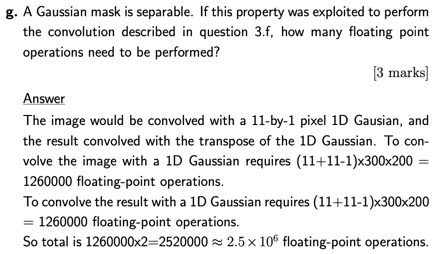

% A Gaussian mask is separable. If this property was exploited to perform the convolution described in question 3.f, how many floating point operations need to be performed?
sepatable_operation = 2 * (gaussian_mask_size(1) + gaussian_mask_size(2) -1) * image_size(1) * image_size(2)

sepatable_operation = 2520000

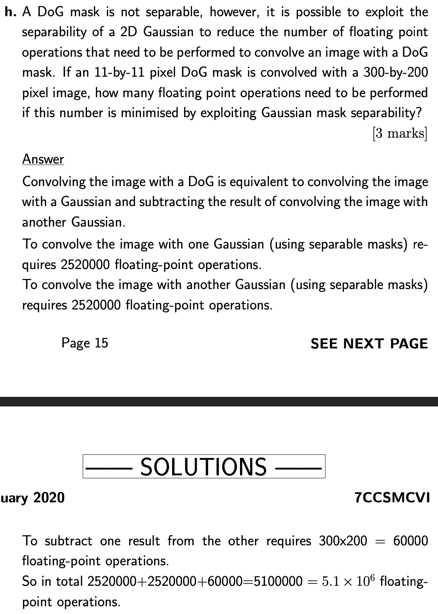

% A DoG mask is not separable, however, it is possible to exploit the separability of a 2D Gaussian to reduce the number of floating point operations that need to be performed to convolve an image with a DoG mask. If an 11-by-11 pixel DoG mask is convolved with a 300-by-200 pixel image, how many floating point operations need to be performed if this number is minimised by exploiting Gaussian mask separability?
sepatable_operation + sepatable_operation + image_size(1) * image_size(2)

ans = 5100000

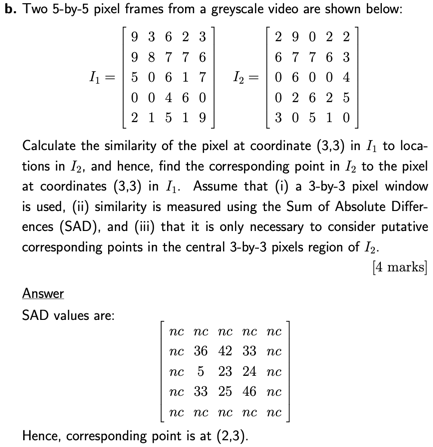

% Calculate the similarity of the pixel at coordinate (3,3) in I1 to loca- tions in I2, and hence, find the corresponding point in I2 to the pixel at coordinates (3,3) in I1. Assume that (i) a 3-by-3 pixel window is used, (ii) similarity is measured using the Sum of Absolute Differ- ences (SAD), and (iii) that it is only necessary to consider putative corresponding points in the central 3-by-3 pixels region of I2.
I1_3_3 = [8 7 7
          0 6 1
          0 4 6];

I2 = [2 9 0 2 2
      6 7 7 6 3
      0 6 0 0 4
      0 2 6 2 5
      3 0 5 1 0];

SAD_value = NaN(5);
for i = 2:4
    for j = 2:4
        SAD_value(i,j) = sum_matrix(abs(I2(i-1:i+1, j-1:j+1) - I1_3_3));
    end
end

SAD_value

SAD_value =    NaN   NaN   NaN   NaN   NaN
   NaN    36    42    33   NaN
   NaN     5    23    24   NaN
   NaN    33    25    46   NaN
   NaN   NaN   NaN   NaN   NaN


% Minimum
coordinating_point = img_find_min(SAD_value)

coordinating_point =      2     3


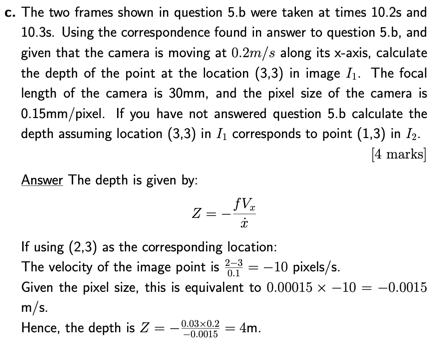

% The two frames shown in question 5.b were taken at times 10.2s and 10.3s. Using the correspondence found in answer to question 5.b, and given that the camera is moving at 0.2m/s along its x-axis, calculate the depth of the point at the location (3,3) in image I1. The focal length of the camera is 30mm, and the pixel size of the camera is 0.15mm/pixel. If you have not answered question 5.b calculate the depth assuming location (3,3) in I1 corresponds to point (1,3) in I2.
focal_length = 30 * 1000^-1; % mm -> m
camera_speed = 0.2;
pixel_size = 0.15 * 1000^-1;
t = 10.3 - 10.2;

velocity = (x-y) / t;
equivalent_speed = velocity * pixel_size;
Z = - focal_length * camera_speed / equivalent_speed

Z = 0.0120

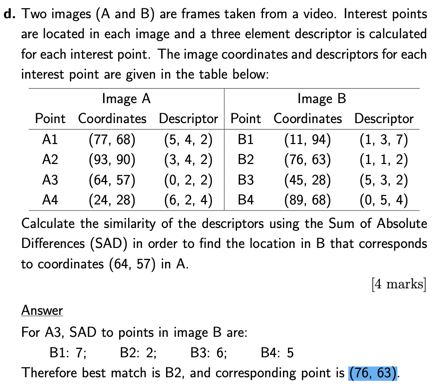

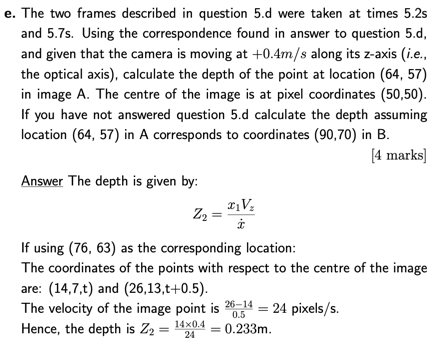

% Two images (A and B) are frames taken from a video. Interest points are located in each image and a three element descriptor is calculated for each interest point. The image coordinates and descriptors for each interest point are given in the table below:
% The two frames described in question 5.d were taken at times 5.2s and 5.7s. Using the correspondence found in answer to question 5.d, and given that the camera is moving at +0.4m/s along its z-axis (i.e., the optical axis), calculate the depth of the point at location (64, 57) in image A. The centre of the image is at pixel coordinates (50,50). If you have not answered question 5.d calculate the depth assuming location (64, 57) in A corresponds to coordinates (90,70) in B.
B2 = [76 63];
t = 5.7 - 5.2;
camera_speed = 0.4;
point = [64, 57];
center = [50 50];

velocity = ((B2(1) - center(1)) - (point(1) - center(1))) / t;
Z = (point(1) - center(1)) * camera_speed / velocity

Z = 0.2333

# Tutorial 2

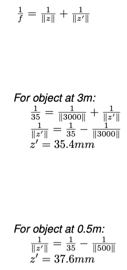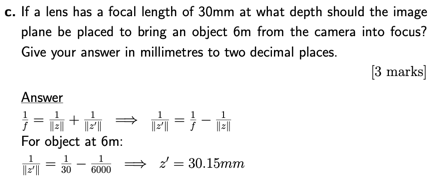

% If a lens has a focal length of 35mm at what depth should the image plane be placed to bring an object 3m from the camera into focus? What if the object is at 0.5m?
f = 35;
z = 3 * 1000; % m -> mm
z = find_depth(f,z)

z = 35.4132


f = 35;
z = 0.5 * 1000; % m -> mm
z = find_depth(f,z)

z = 37.6344


f = 30;
z = 6 * 1000;
z = find_depth(f,z)

z = 30.1508

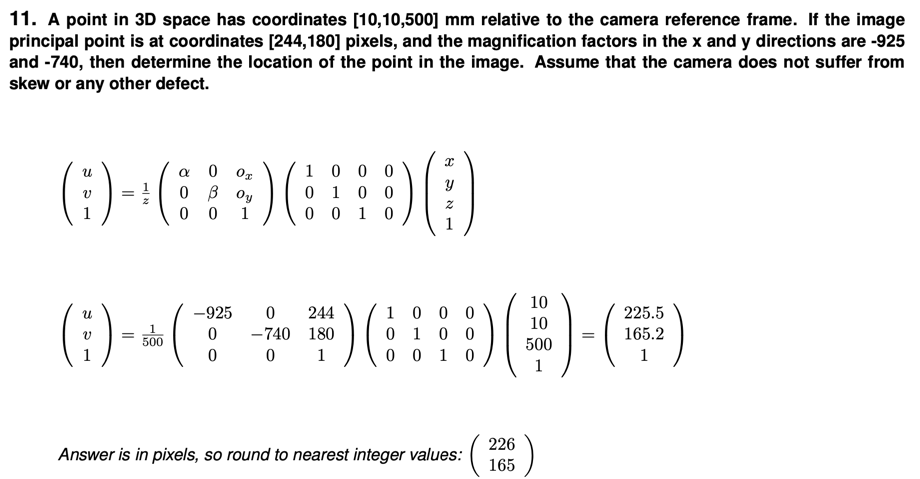

% A point in 3D space has coordinates [10,10,500] mm relative to the camera reference frame. If the image principal point is at coordinates [244,180] pixels, and the magnification factors in the x and y directions are -925 and -740, then determine the location of the point in the image. Assume that the camera does not suffer from skew or any other defect.
principal_point = [244 180];
x = -925;
y = -740;
point = [10 10 500];

nearest_integer_values = location_in_img(x,y,principal_point,point)

nearest_integer_values =   225.5000
  165.2000
    1.0000


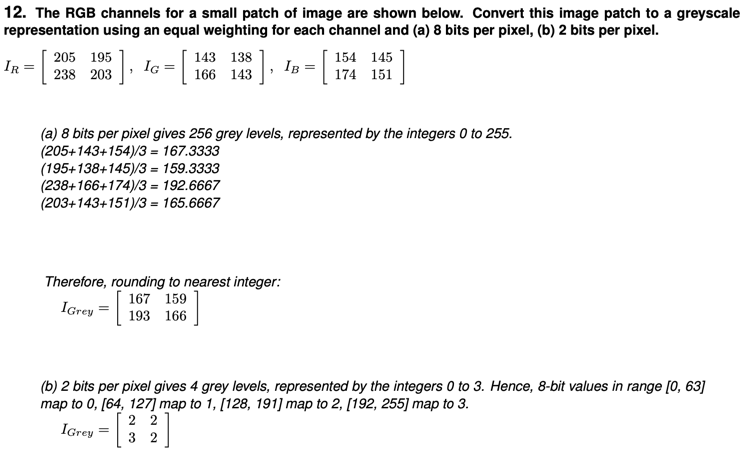

% The RGB channels for a small patch of image are shown below. Convert this image patch to a greyscale representation using an equal weighting for each channel and (a) 8 bits per pixel, (b) 2 bits per pixel.
IR = [205 195
      238 203];
IG = [143 138
      166 143];
IB = [154 145
      174 151];


rgb(:,:,1) = IR;
rgb(:,:,2) = IG;
rgb(:,:,3) = IB;

% 8bit
I_gray_8 = mean(rgb,3)

I_gray_8 =   167.3333  159.3333
  192.6667  165.6667



% 2bit
I_gray_2 = zeros(2);
for i = 1:4
    if I_gray_8(i) <= 63
        I_gray_2(i) = 0;
    
    elseif I_gray_8(i) <= 127
        I_gray_2(i) = 1;
    elseif I_gray_8(i) <= 191
        I_gray_2(i) = 2;
    else
        I_gray_2(i) = 3;
    end
end

I_gray_2

I_gray_2 =      2     2
     3     2


# Tutorial 3

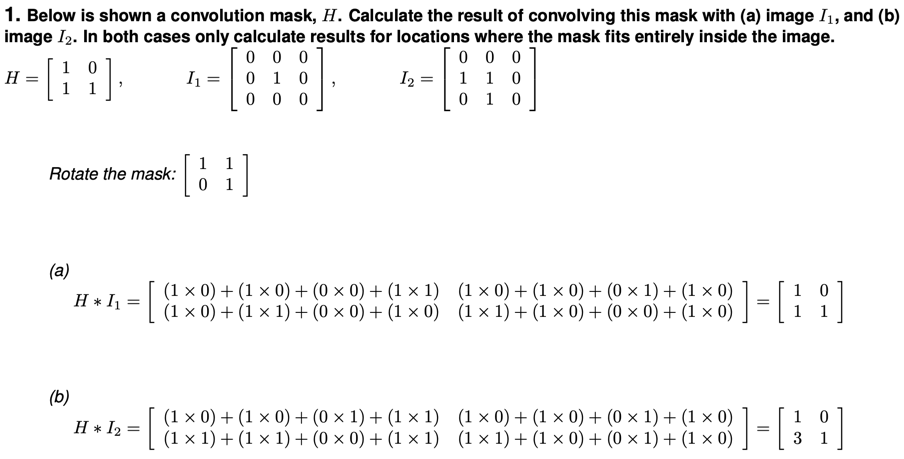

% Below is shown a convolution mask, H. Calculate the result of convolving this mask with (a) image I1, and (b) image I2. In both cases only calculate results for locations where the mask fits entirely inside the image.
H = [1 0
     1 1];

I1 = [0 0 0
      0 1 0
      0 0 0];

I2 = [0 0 0
      1 1 0
      0 1 0];

a = conv2(I1, H, "valid")

a =      1     0
     1     1


b = conv2(I2, H, "valid")

b =      1     0
     3     1


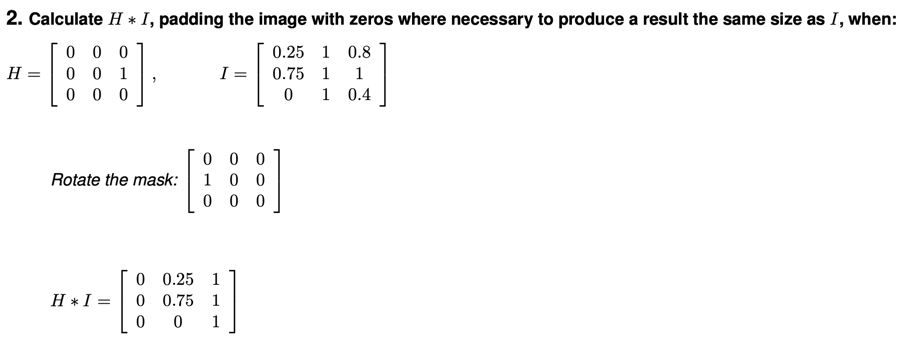

% Calculate H ∗ I, padding the image with zeros where necessary to produce a result the same size as I, when:
H = [0 0 0
     0 0 1
     0 0 0];

I = [0.25 1 0.8
     0.75 1 1
     0 1 0.4];

conv2(I, H, "same")

ans =          0    0.2500    1.0000
         0    0.7500    1.0000
         0         0    1.0000


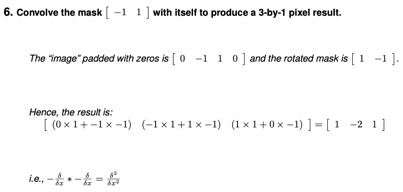

% Convolve the mask [−1 1] with itself to produce a 3-by-1 pixel result.
mask = [-1 1]

mask =     -1     1


conv2(mask, mask,"full")

ans =      1    -2     1


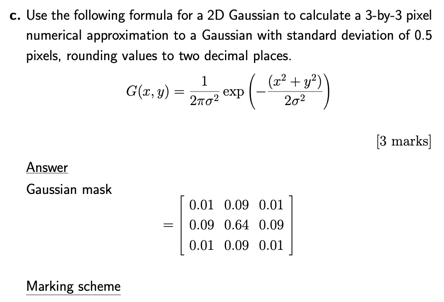

% 2016-2017, p11
% Use the following formula for a 2D Gaussian to calculate a 3-by-3 pixel numerical approximation to a Gaussian with standard deviation of 0.50 pixels, rounding values to two decimal places.
std = 0.50;

gaussian_mask = gaussian2D(std)

gaussian_mask =     0.0100    0.0900    0.0100
    0.0900    0.6400    0.0900
    0.0100    0.0900    0.0100


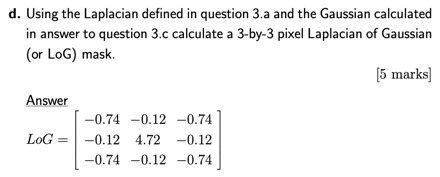

% Using the Laplacian defined in question 3.a and the Gaussian calculated in answer to question 3.c calculate a 3-by-3 pixel Laplacian of Gaussian (or LoG) mask.
L = [-1 -1 -1
     -1 8 -1
     -1 -1 -1];

% it's a continuous question of the previous question -> has to get gaussian2D
LoG = conv2(L, gaussian_mask, "same")

LoG =    -0.7400   -0.1200   -0.7400
   -0.1200    4.7200   -0.1200
   -0.7400   -0.1200   -0.7400


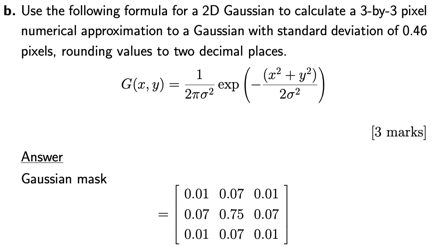

% 2017-2018,p11
% Use the following formula for a 2D Gaussian to calculate a 3-by-3 pixel numerical approximation to a Gaussian with standard deviation of 0.46 pixels, rounding values to two decimal places.
std = 0.46;

% only for 3 by 3
gaussian_mask = gaussian2D(std)

gaussian_mask =     0.0100    0.0700    0.0100
    0.0700    0.7500    0.0700
    0.0100    0.0700    0.0100


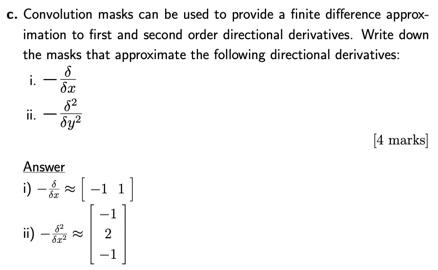

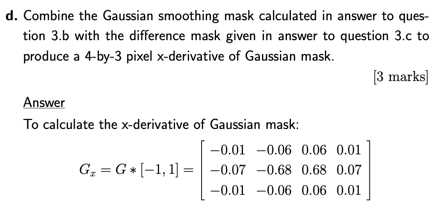

% Combine the Gaussian smoothing mask calculated in answer to ques- tion 3.b with the difference mask given in answer to question 3.c to produce a 4-by-3 pixel x-derivative of Gaussian mask.
first_order_directional_derivatives = [-1 1];

Gx = conv2(gaussian_mask, first_order_directional_derivatives, "full")

Gx =    -0.0100   -0.0600    0.0600    0.0100
   -0.0700   -0.6800    0.6800    0.0700
   -0.0100   -0.0600    0.0600    0.0100


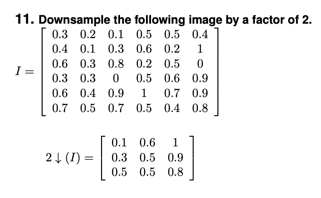

% Downsample the following image by a factor of 2.
I = [0.3 0.2 0.1 0.5 0.5 0.4
     0.4 0.1 0.3 0.6 0.2 1
     0.6 0.3 0.8 0.2 0.5 0
     0.3 0.3 0 0.5 0.6 0.9
     0.6 0.4 0.9 1 0.7 0.9
     0.7 0.5 0.7 0.5 0.4 0.8];

factor = 2;

I(factor:factor:end, factor:factor:end)

ans =     0.1000    0.6000    1.0000
    0.3000    0.5000    0.9000
    0.5000    0.5000    0.8000


# Tutorial 5

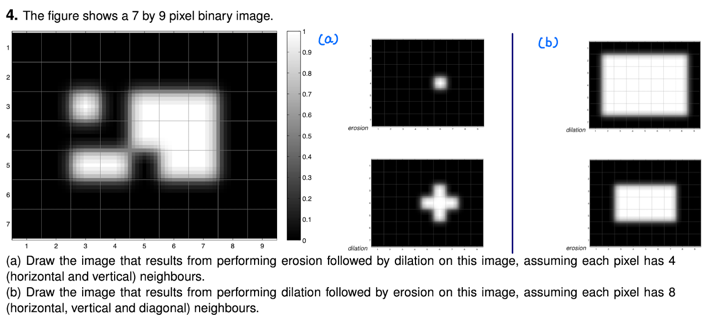

% (a) Draw the image that results from performing erosion followed by dilation on this image, assuming each pixel has 4 (horizontal and vertical) neighbours.
% (b) Draw the image that results from performing dilation followed by erosion on this image, assuming each pixel has 8 (horizontal, vertical and diagonal) neighbours.
im = [zeros(2,9)
    0 0 1 0 1 1 1 0 0
    0 0 0 0 1 1 1 0 0
    0 0 1 1 0 1 1 0 0
    zeros(2,9)];

% 4 neighbours
SE_4 = strel("diamond", 1);
erosion_4_neighbours = imerode(im, SE_4)

erosion_4_neighbours =      0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     1     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0


dailation_4_neighbours = imdilate(erosion_4_neighbours, SE_4)

dailation_4_neighbours =      0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     1     0     0     0
     0     0     0     0     1     1     1     0     0
     0     0     0     0     0     1     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0



% 8 neighbours
SE_8 = strel("square",3);
dailation_8_neighbours = imdilate(im, SE_8)

dailation_8_neighbours =      0     0     0     0     0     0     0     0     0
     0     1     1     1     1     1     1     1     0
     0     1     1     1     1     1     1     1     0
     0     1     1     1     1     1     1     1     0
     0     1     1     1     1     1     1     1     0
     0     1     1     1     1     1     1     1     0
     0     0     0     0     0     0     0     0     0


erosion_8_neighbours = imerode(dailation_8_neighbours, SE_8)

erosion_8_neighbours =      0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     1     1     1     1     1     0     0
     0     0     1     1     1     1     1     0     0
     0     0     1     1     1     1     1     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0


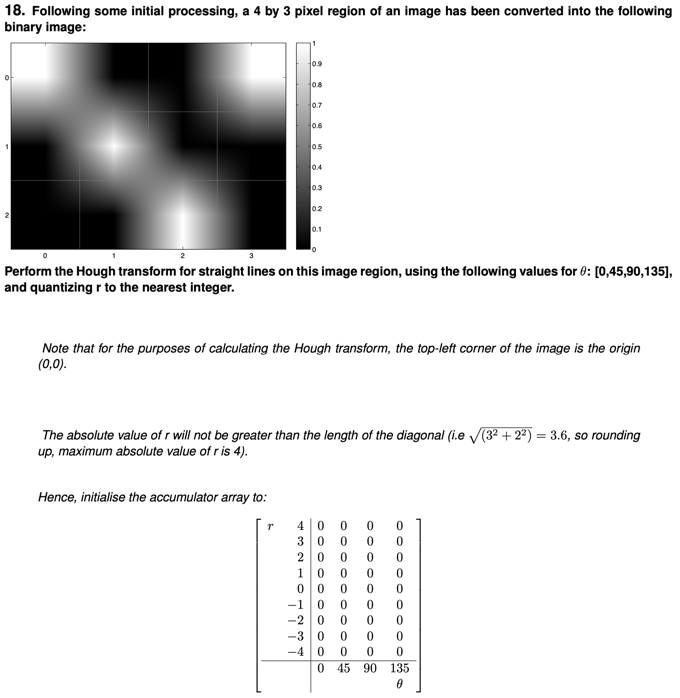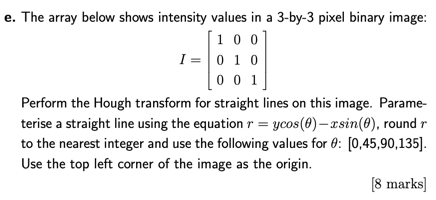

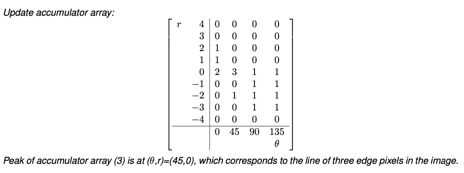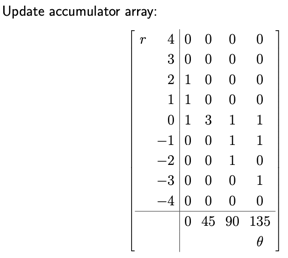

% Perform the Hough transform for straight lines on this image region, using the following values for θ: [0,45,90,135], and quantizing r to the nearest integer.
pixel_1 = [0 0];
pixel_2 = [1 1];
pixel_3 = [2 2];
pixel_4 = [3 0];

thetas = [0 45 90 135]

thetas =      0    45    90   135



% Count how many different numbers that each column has 
cal_lines(pixel_1, thetas)

ans =      0     0     0     0



cal_lines(pixel_2, thetas)

ans =      1     0    -1    -1



cal_lines(pixel_3, thetas)

ans =      2     0    -2    -3



cal_lines(pixel_4, thetas)

ans =      0    -2    -3    -2



% Peak of accumulator array (3) is at (θ,r)=(45,0), 
% which corresponds to the line of three edge pixels in the image.

# Tutorial 6

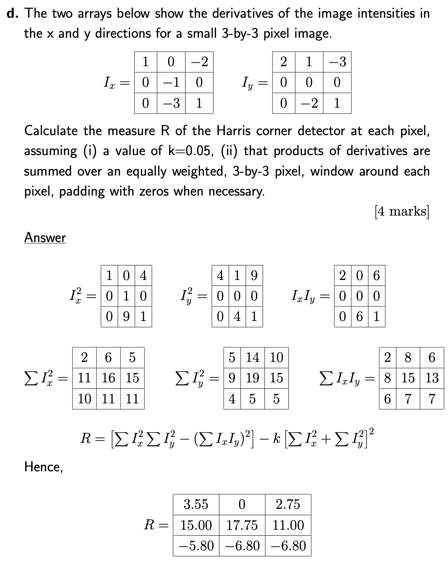

% 2016-17, p23
% Given the x any y derivatives of the image intensities shown above, calculate the response of the Harris corner detector at each of the six central pixels, assuming (a) a value of k=0.05, (b) that products of derivatives are summed over an equally weighted, 3 by 3 pixel, window around each pixel.

k = 0.05;

% Ix and Iy can be any size
Ix = [1 0 -2
      0 -1 0
      0 -3 1];

Iy = [2 1 -3
      0 0 0
      0 -2 1];

Ix_Iy = Ix .* Iy;

Ix_2 = Ix .^2;
Iy_2 = Iy .^2;

mask = [1 1 1
        1 1 1
        1 1 1];

sum_Ix_2 = conv2(Ix_2, mask, "same");
sum_Iy_2 = conv2(Iy_2, mask, "same");
sum_Ix_Iy = conv2(Ix_Iy, mask, "same");

R = (sum_Ix_2 .* sum_Iy_2 - sum_Ix_Iy .^2) - k * (sum_Ix_2 + sum_Iy_2) .^2

R =     3.5500         0    2.7500
   15.0000   17.7500   11.0000
   -5.8000   -6.8000   -6.8000


# Tutorial 8

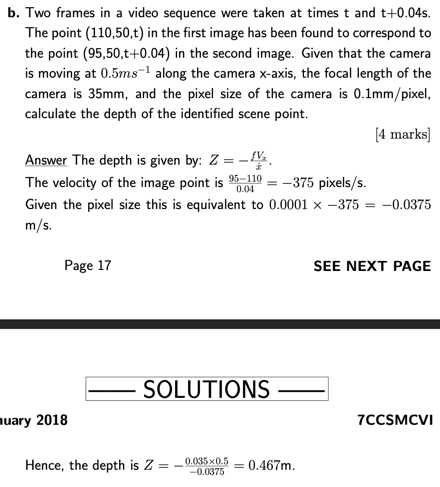

% 2017-2018, p17
% Two frames in a video sequence were taken at times t and t+0.04s. The point (110,50,t) in the first image has been found to correspond to the point (95,50,t+0.04) in the second image. Given that the camera is moving at 0.5ms−1 along the camera x-axis, the focal length of the camera is 35mm, and the pixel size of the camera is 0.1mm/pixel, calculate the depth of the identified scene point.
first_point = [110, 50];
second_point = [95, 50];
focal_length = 35 * 100^-1; % mm -> m
time = 0.04;
cam_velocity = 0.5;
pixel_size = 0.1 * 100^-1; % mm -> m

img_velocity = (second_point(1) - first_point(1)) / time;
equivalent_pixel_size = pixel_size * img_velocity;

Z = - (focal_length * cam_velocity) / equivalent_pixel_size

Z = 0.4667

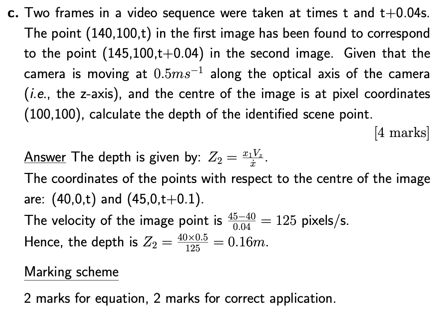

% 2017-2018, p18
% Two frames in a video sequence were taken at times t and t+0.04s. The point (140,100,t) in the first image has been found to correspond to the point (145,100,t+0.04) in the second image. Given that the camera is moving at 0.5ms−1 along the optical axis of the camera (i.e., the z-axis), and the centre of the image is at pixel coordinates (100,100), calculate the depth of the identified scene point.
first_point = [140, 100];
second_point = [145, 100];
center_point = [100, 100];
time = 0.04;
cam_velocity = 0.5;

% use x-coordinates
point_t = first_point - center_point;
point_t_1 = second_point - center_point;
img_velocity = (point_t_1(1) - point_t(1)) / time;

Z = (point_t(1) * cam_velocity) / img_velocity

Z = 0.1600

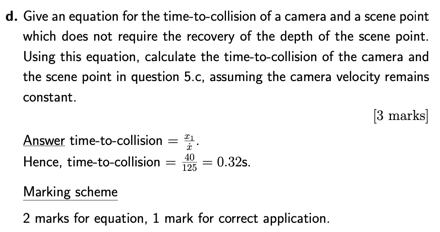

% 2017-2018, p18
% Give an equation for the time-to-collision of a camera and a scene point which does not require the recovery of the depth of the scene point. Using this equation, calculate the time-to-collision of the camera and the scene point in question 5.c, assuming the camera velocity remains constant.
time_to_collision = point_t(1) / img_velocity

time_to_collision = 0.3200

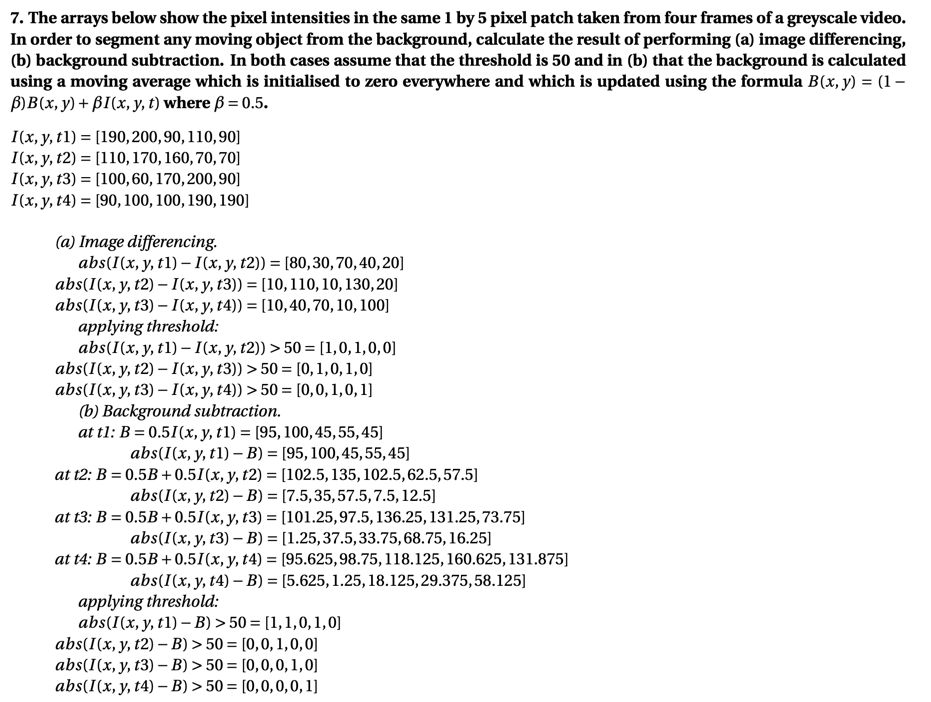

% The arrays below show the pixel intensities in the same 1 by 5 pixel patch taken from four frames of a greyscale video. In order to segment any moving object from the background, calculate the result of performing (a) image differencing, (b) background subtraction. In both cases assume that the threshold is 50 and in (b) that the background is calculated using a moving average which is initialised to zero everywhere and which is updated using the formula B(x,y) = (1− β)B(x,y)+βI(x,y,t) where β = 0.5.
I_t1 = [190 200 90 110 90];
I_t2 = [110 170 160 70 70];
I_t3 = [100 60 170 200 90];
I_t4 = [90 100 100 190 190];
th = 50;
beta = 0.5;

% Image differencing
abs(I_t1 - I_t2)

ans =     80    30    70    40    20


abs(I_t2 - I_t3)

ans =     10   110    10   130    20


abs(I_t3 - I_t4)

ans =     10    40    70    10   100


% applying threshold
t1_t2 = abs(I_t1 - I_t2) > th

t1_t2 = 1×5 logical array
   1   0   1   0   0


t2_t3 = abs(I_t2 - I_t3) > th

t2_t3 = 1×5 logical array
   0   1   0   1   0


t3_t4 = abs(I_t3 - I_t4) > th

t3_t4 = 1×5 logical array
   0   0   1   0   1



% Background subtraction
t1_B = background_subtraction(I_t1, 0, beta);
t2_B = background_subtraction(I_t2, t1_B, beta);
t3_B = background_subtraction(I_t3, t2_B, beta);
t4_B = background_subtraction(I_t4, t3_B, beta);
abs(I_t1 - t1_B)

ans = 1×5
    95   100    45    55    45


abs(I_t2 - t2_B)

ans = 1×5
    7.5000   35.0000   57.5000    7.5000   12.5000


abs(I_t3 - t3_B)

ans = 1×5
    1.2500   37.5000   33.7500   68.7500   16.2500


abs(I_t4 - t4_B)

ans = 1×5
    5.6250    1.2500   18.1250   29.3750   58.1250



% applying threshold
t1 = abs(I_t1 - t1_B) > th

t1 = 1×5 logical array
   1   1   0   1   0


t2 = abs(I_t2 - t2_B) > th

t2 = 1×5 logical array
   0   0   1   0   0


t3 = abs(I_t3 - t3_B) > th

t3 = 1×5 logical array
   0   0   0   1   0


t4 = abs(I_t4 - t4_B) > th

t4 = 1×5 logical array
   0   0   0   0   1


# Tutorial 9

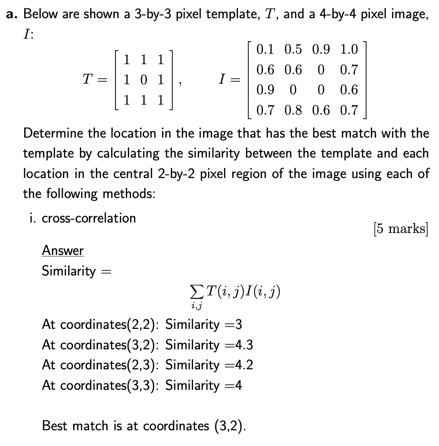

% 2019-2020, p30
% Determine the location in the image that has the best match with the template by calculating the similarity between the template and each location in the central 2-by-2 pixel region of the image using each of the following methods: i. cross-correlation, ii. normalised cross-correlation, iii. Euclidean distance
T = [1 1 1
     1 0 1
     1 1 1];

% It's a cross-correlation, not a convolution, rotate it bafore the conv2
% rotate it -> not be rotated
T_180 = rot90(T, 90);

I = [0.1 0.5 0.9 1.0
     0.6 0.6 0 0.7
     0.9 0 0 0.6
     0.7 0.8 0.6 0.7];

% maximum
similarity = conv2(I, T_180, "valid");
padded = padarray(similarity,[1 1], NaN)

padded = 4×4
       NaN       NaN       NaN       NaN
       NaN    3.0000    4.3000       NaN
       NaN    4.2000    4.0000       NaN
       NaN       NaN       NaN       NaN


best_match_at_coordinate = img_find_max(padded)

best_match_at_coordinate = 1×2
     3     2


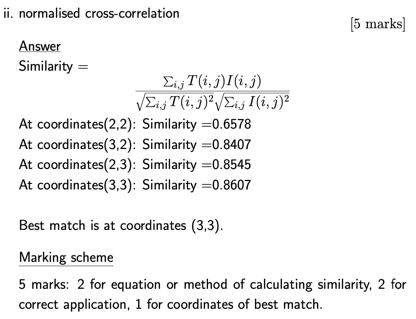

% Normalized cross-correlation
similarity = NaN(4);
for i = 2:3
    for j = 2:3
        similarity(i,j) = sum_matrix(T .* I(i-1:i+1, j-1:j+1)) / (sqrt(sum_matrix(T.^2)) * sqrt(sum_matrix(I(i-1:i+1, j-1:j+1).^2)));
    end
end

similarity

similarity = 4×4
       NaN       NaN       NaN       NaN
       NaN    0.6578    0.8407       NaN
       NaN    0.8545    0.8607       NaN
       NaN       NaN       NaN       NaN


% Maximum
best_match_at_coordinate = img_find_max(similarity)

best_match_at_coordinate = 1×2
     3     3


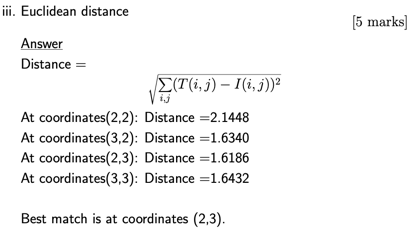

% Euclidean distance
euclidean = NaN(4);
for i = 2:3
    for j = 2:3
        euclidean(i,j) = sqrt(sum_matrix((T -  I(i-1:i+1, j-1:j+1)).^2));
    end
end

% Minimum
euclidean

euclidean = 4×4
       NaN       NaN       NaN       NaN
       NaN    2.1448    1.6340       NaN
       NaN    1.6186    1.6432       NaN
       NaN       NaN       NaN       NaN


best_match_at_coordinate = img_find_min(euclidean)

best_match_at_coordinate = 1×2
     2     3


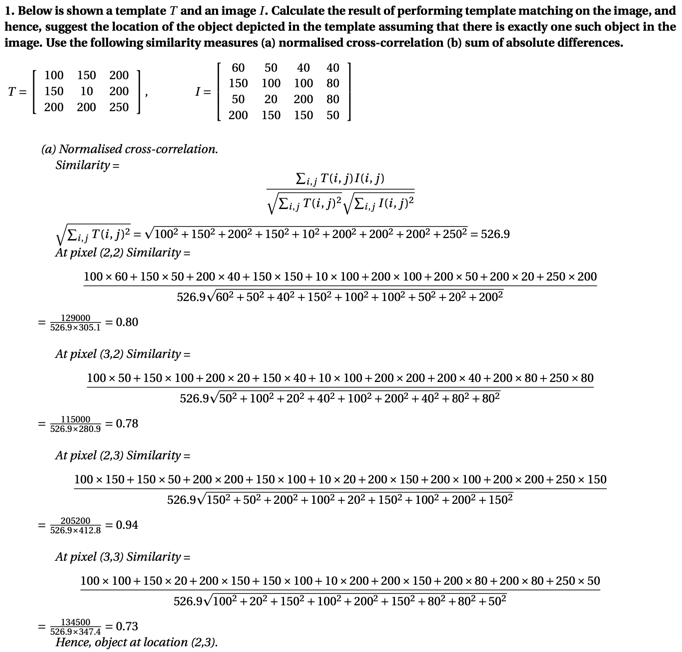

% 1. Below is shown a template T and an image I . Calculate the result of performing template matching on the image, and hence, suggest the location of the object depicted in the template assuming that there is exactly one such object in the image. Use the following similarity measures (a) normalised cross-correlation (b) sum of absolute differences.
% Normalized cross-correlation
T = [100 150 200
     150 10 200
     200 200 250];

I = [60 50 40 40
     150 100 100 80
     50 20 200 80
     200 150 150 50];

similarity = NaN(4);
for i = 2:3
    for j = 2:3
        similarity(i,j) = sum_matrix(T .* I(i-1:i+1, j-1:j+1)) / (sqrt(sum_matrix(T.^2)) * sqrt(sum_matrix(I(i-1:i+1, j-1:j+1).^2)));
    end
end

similarity

similarity = 4×4
       NaN       NaN       NaN       NaN
       NaN    0.8024    0.7771       NaN
       NaN    0.9435    0.7348       NaN
       NaN       NaN       NaN       NaN


% Maximum
object_at_location = img_find_max(similarity)

object_at_location = 1×2
     2     3


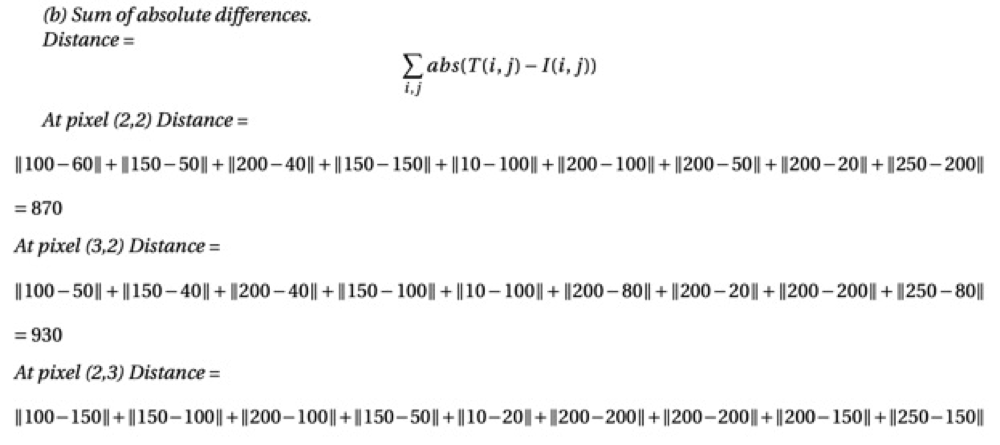

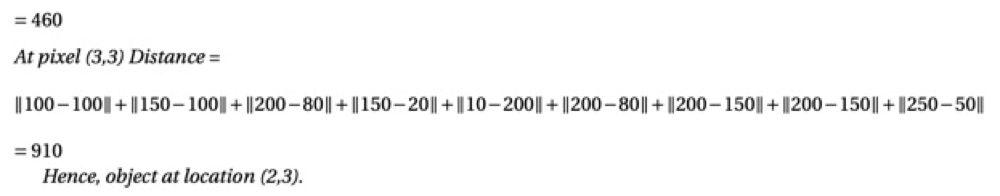

% Sum of absolute difference
SAD = NaN(4);
for i = 2:3
    for j = 2:3
        SAD(i,j) = sum_matrix(abs(T - I(i-1:i+1,j-1:j+1)));
    end
end

% minimum
object_at_location = img_find_min(SAD)

object_at_location = 1×2
     2     3


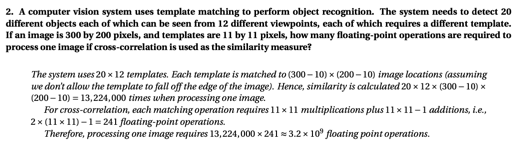

% A computer vision system uses template matching to perform object recognition. The system needs to detect 20 different objects each of which can be seen from 12 different viewpoints, each of which requires a different template. If an image is 300 by 200 pixels, and templates are 11 by 11 pixels, how many floating-point operations are required to process one image if cross-correlation is used as the similarity measure?
different_objects = 20;
different_viewpoints = 12;
image = [300 200];
template = [11 11];

similarity_calculation_times = different_objects * different_viewpoints * (image(1) - template(1) + 1) * (image(2) - template(2) + 1)

similarity_calculation_times = 13224000

matching_operation = 2 * template(1) * template(2) - 1

matching_operation = 241

floating_point_operation = similarity_calculation_times * matching_operation

floating_point_operation = 3.1870e+09

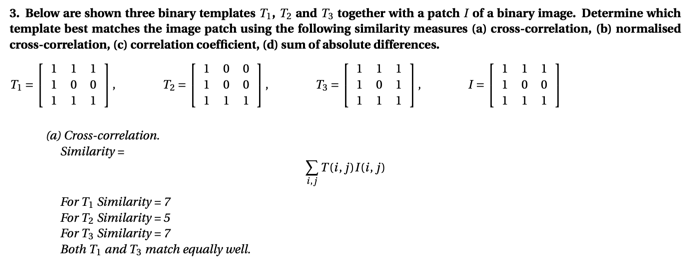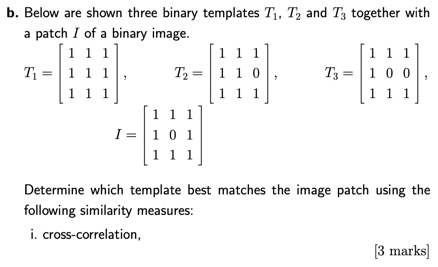

% Below are shown three binary templates T1, T2 and T3 together with a patch I of a binary image. Determine which template best matches the image patch using the following similarity measures (a) cross-correlation, (b) normalised cross-correlation, (c) correlation coefficient, (d) sum of absolute differences.
T1 = [1 1 1
      1 0 0
      1 1 1];

T2 = [1 0 0
      1 0 0
      1 1 1];

T3 = [1 1 1
      1 0 1
      1 1 1];

I = [1 1 1
     1 0 0
     1 1 1];

% (a) cross-correlation -> Maximum
T1_180 = rot90(T1, 90);
T1_numerator = conv2(I,T1_180,"valid")

T1_numerator = 7


T2_180 = rot90(T2, 90);
T2_numerator = conv2(I,T2_180,"valid")

T2_numerator = 5


T3_180 = rot90(T3, 90);
T3_numerator = conv2(I,T3_180,"valid")

T3_numerator = 7

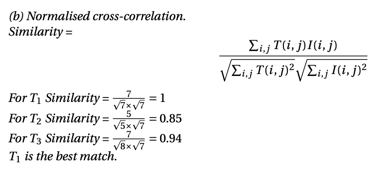

sqrt_sum_T1_2 = sqrt(sum(sum(T1.^2)));
sqrt_sum_T2_2 = sqrt(sum(sum(T2.^2)));
sqrt_sum_T3_2 = sqrt(sum(sum(T3.^2)));
I_2 = I.^2;

% (b) normalised cross-correlation -> Maximum
T1_similarity = T1_numerator / (sqrt_sum_T1_2 * sqrt(sum_matrix(I_2)))

T1_similarity = 1.0000

T2_similarity = T2_numerator / (sqrt_sum_T2_2 * sqrt(sum_matrix(I_2)))

T2_similarity = 0.8452

T3_similarity = T3_numerator / (sqrt_sum_T3_2 * sqrt(sum_matrix(I_2)))

T3_similarity = 0.9354

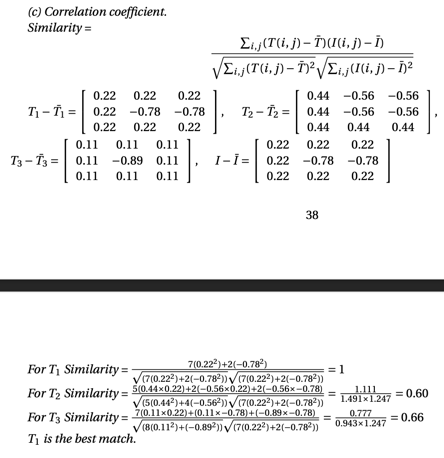

% (c) correlation coefficient -> Maximum
T1_similarity = corr2(T1, I)

T1_similarity = 1

T2_similarity = corr2(T2, I)

T2_similarity = 0.5976

T3_similarity = corr2(T3, I)

T3_similarity = 0.6614

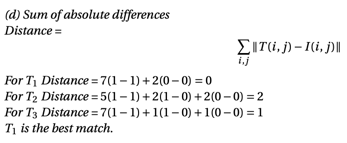

% (d) sum of absolute differences -> Minimum
T1_distance = sum_matrix(abs(T1-I))

T1_distance = 0

T2_distance = sum_matrix(abs(T2-I))

T2_distance = 2

T3_distance = sum_matrix(abs(T3-I))

T3_distance = 1

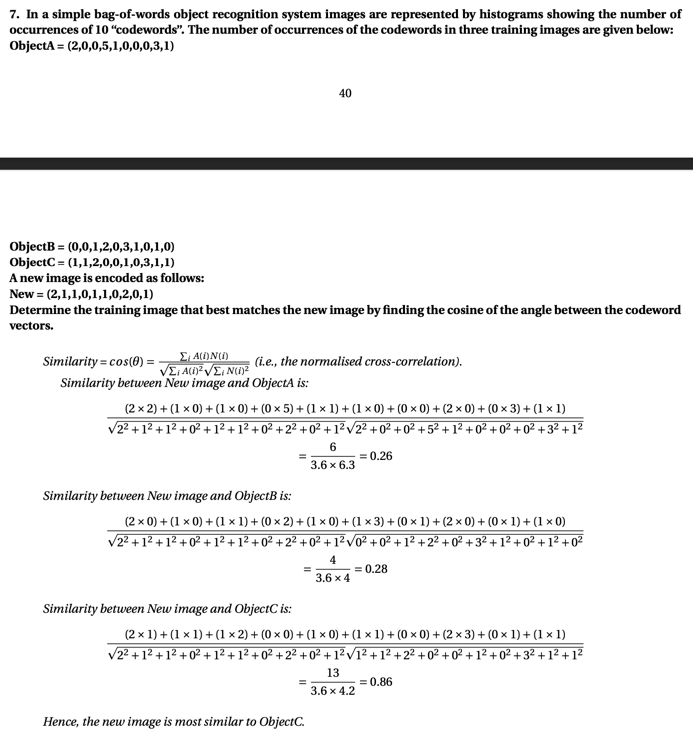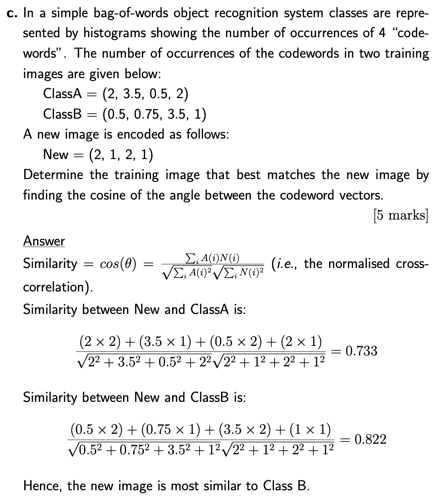

% In a simple bag-of-words object recognition system images are represented by histograms showing the number of occurrences of 10 “codewords”. The number of occurrences of the codewords in three training images are given below: ObjectA = (2,0,0,5,1,0,0,0,3,1)
O_A = [2 3.5 0.5 2];
O_B = [0.5 0.75 3.5 1];
new = [2 1 2 1];

% Miximum
similarity_between_new_and_class_A = sum(O_A .* new) / (sqrt(sum(O_A.^2)) * sqrt(sum(new.^2)))

similarity_between_new_and_class_A = 0.7334

similarity_between_new_and_class_B = sum(O_B .* new) / (sqrt(sum(O_B.^2)) * sqrt(sum(new.^2)))

similarity_between_new_and_class_B = 0.8222

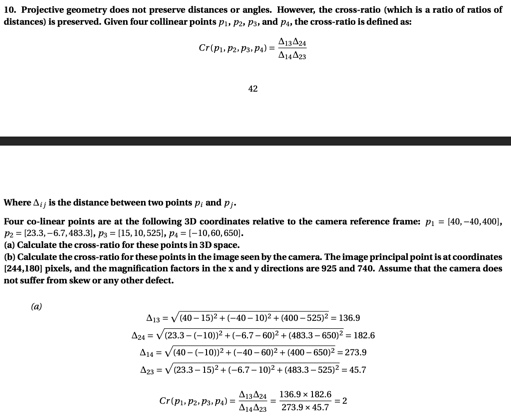

% Projective geometry does not preserve distances or angles. However, the cross-ratio (which is a ratio of ratios of distances) is preserved. Given four collinear points p1, p2, p3, and p4, the cross-ratio is defined as: Where ∆ij is the distance between two points pi and pj. Four co-linear points are at the following 3D coordinates relative to the camera reference frame: p1 = [40,−40,400], p2 = [23.3,−6.7,483.3], p3 = [15,10,525], p4 = [−10,60,650]. (a) Calculate the cross-ratio for these points in 3D space. (b) Calculate the cross-ratio for these points in the image seen by the camera. The image principal point is at coordinates [244,180] pixels, and the magnification factors in the x and y directions are 925 and 740. Assume that the camera does not suffer from skew or any other defect.
p1 = [40 -40 400];
p2 = [23.3 -6.7 483.3];
p3 = [15 10 525];
p4 = [-10 60 650];

delta_13 = sqrt(sum((p1-p3).^2))

delta_13 = 136.9306

delta_24 = sqrt(sum((p2-p4).^2))

delta_24 = 182.6107

delta_14 = sqrt(sum((p1-p4).^2))

delta_14 = 273.8613

delta_23 = sqrt(sum((p2-p3).^2))

delta_23 = 45.6801


Cr = (delta_13 * delta_24) / (delta_14 * delta_23)

Cr = 1.9988

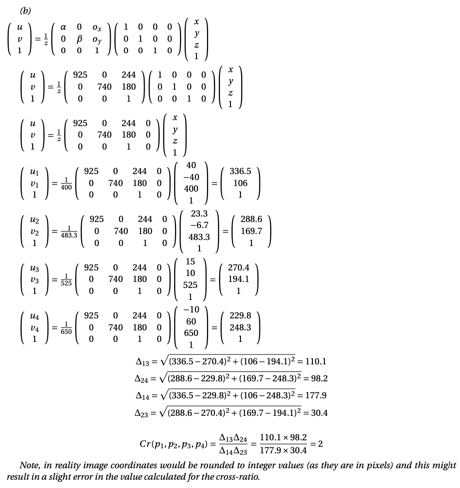

principal_point = [244 180];
x = 925;
y = 740;

p1_img = location_in_img(x,y,principal_point,p1);
p2_img = location_in_img(x,y,principal_point,p2);
p3_img = location_in_img(x,y,principal_point,p3);
p4_img = location_in_img(x,y,principal_point,p4);

delta_13 = sqrt(sum((p1_img(1:2) - p3_img(1:2)).^2))

delta_13 = 110.1190

delta_24 = sqrt(sum((p2_img(1:2) - p4_img(1:2)).^2))

delta_24 = 98.1482

delta_14 = sqrt(sum((p1_img(1:2) - p4_img(1:2)).^2))

delta_14 = 177.8846

delta_23 = sqrt(sum((p2_img(1:2) - p3_img(1:2)).^2))

delta_23 = 30.3827


Cr = (delta_13 * delta_24) / (delta_14 * delta_23)

Cr = 1.9998

# Tutorial 10

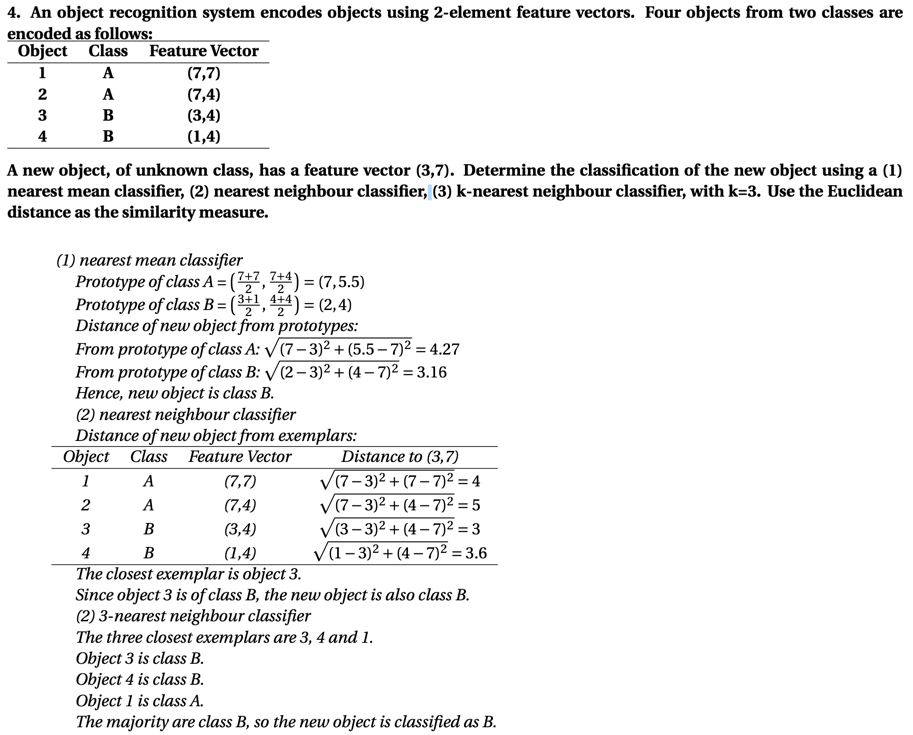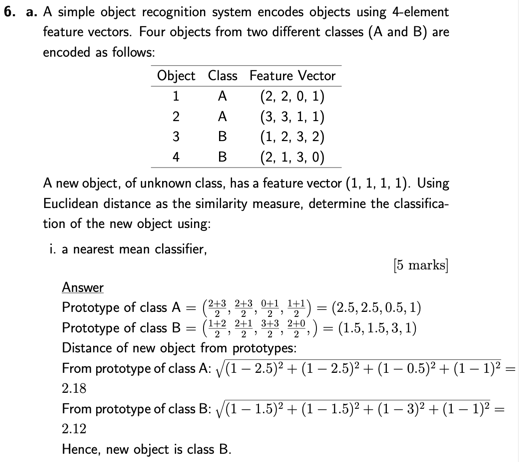

% An object recognition system encodes objects using 2-element feature vectors. Four objects from two classes are encoded as follows: A new object, of unknown class, has a feature vector (3,7). Determine the classification of the new object using a (1) nearest mean classifier, (2) nearest neighbour classifier, (3) k-nearest neighbour classifier, with k=3. Use the Euclidean distance as the similarity measure.
obj1_A = [7 7];
obj2_A = [7 4];
obj3_B = [3 4];
obj4_B = [1 4];
new_obj = [3 7];

% (1) Nearest mean classifier
prototype_A = (obj1_A + obj2_A) / 2;
prototype_B = (obj3_B + obj4_B) / 2;
% minimum
distance_from_A_to_new_obj = pdist2(prototype_A, new_obj, "euclidean")

distance_from_A_to_new_obj = 4.2720

distance_from_B_to_new_obj = pdist2(prototype_B, new_obj, "euclidean")

distance_from_B_to_new_obj = 3.1623


% (2) Nearest neighbour classifier
% Minimum
distance_from_obj1_to_new_obj = pdist2(obj1_A, new_obj, "euclidean")

distance_from_obj1_to_new_obj = 4

distance_from_obj2_to_new_obj = pdist2(obj2_A, new_obj, "euclidean")

distance_from_obj2_to_new_obj = 5

distance_from_obj3_to_new_obj = pdist2(obj3_B, new_obj, "euclidean")

distance_from_obj3_to_new_obj = 3

distance_from_obj4_to_new_obj = pdist2(obj4_B, new_obj, "euclidean")

distance_from_obj4_to_new_obj = 3.6056


% (3) 3-nearest neighbour classifier
% The three closest examplars are 3,4 and 1.
% Object 3 is class B.
% Object 4 is class B.
% Object 1 is class A.
% The majority are class B, so the new object is classified as B.

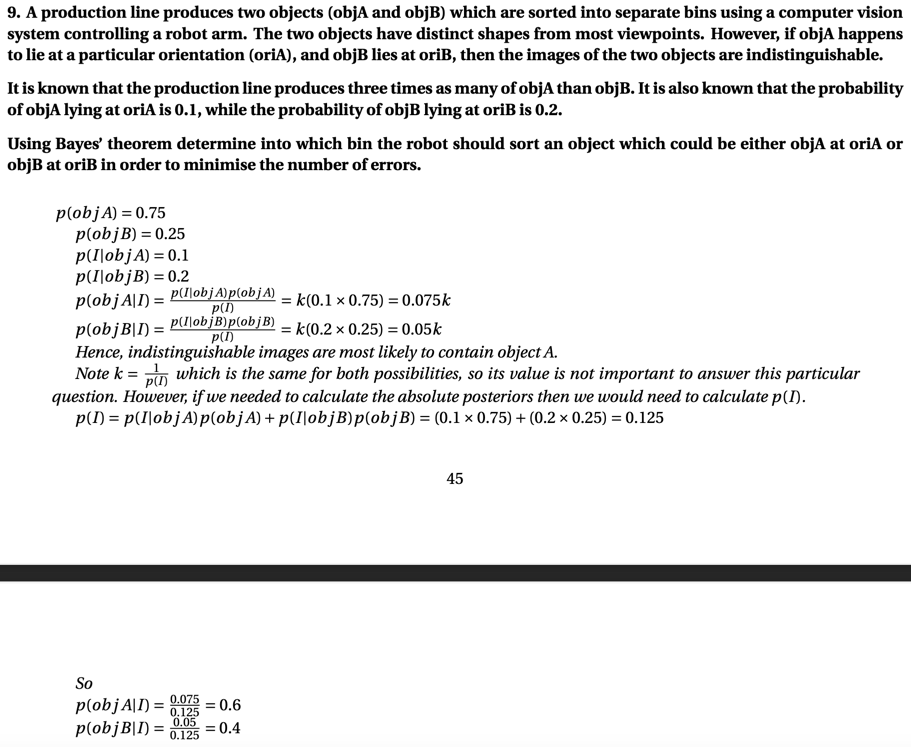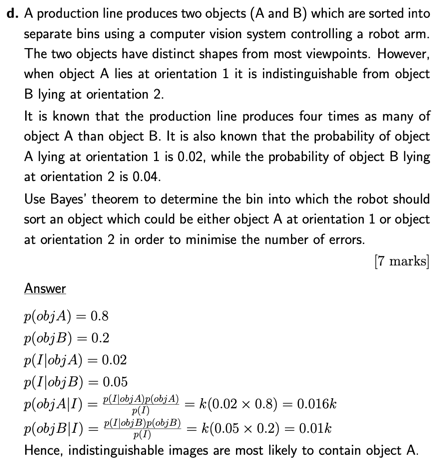

% A production line produces two objects (objA and objB) which are sorted into separate bins using a computer vision system controlling a robot arm. The two objects have distinct shapes from most viewpoints. However, if objA happens to lie at a particular orientation (oriA), and objB lies at oriB, then the images of the two objects are indistinguishable. It is known that the production line produces three times as many of objA than objB. It is also known that the probability of objA lying at oriA is 0.1, while the probability of objB lying at oriB is 0.2. Using Bayes  theorem determine into which bin the robot should sort an object which could be either objA at oriA or objB at oriB in order to minimise the number of errors.
% P_A + P_B = 1
P_A = 0.75;
P_B = 0.25;
P_I_given_A = 0.1;
P_I_given_B = 0.2;
P_I = P_I_given_A * P_A + P_I_given_B * P_B;

% Maximum
P_A_given_I = P_I_given_A * P_A / P_I

P_A_given_I = 0.6000

P_B_given_I = P_I_given_B * P_B / P_I

P_B_given_I = 0.4000

function out = location_in_img(x,y,principal_point,p)
    matrix = [x 0 principal_point(1) 0
              0 y principal_point(2) 0
              0 0 1 0];
    p_T = p.';
    p_T(4) = 1;
    out = 1/p(3) * matrix * p_T;
end

function out = img_find_max(img)
    maximum = max(max(img));
    [y,x] = find(img == maximum);
    out = [x y];
end

function out = img_find_min(img)
    minimum = min(min(img));
    [y,x] = find(img == minimum);
    out = [x y];
end

function [zero, one] = intensity_histogram(I)
    [x, y] = size(I);
    zero = x * y - sum_matrix(I);
    one = sum_matrix(I);
end

function out = cal_distance(R,G,B,c)
    distance = zeros(3);
    for i = 1:3
        for j = 1:3
            temp = [R(i,j) G(i,j) B(i,j)];
            distance(i,j) = sum_matrix(abs(temp - c));
        end
    end
    out = distance;
end

function [c1,c2] = cal_new_center(R,G,B,closest_cluster_center)
    new_c1 = [0 0 0];
    new_c1_count = 0;
    
    new_c2 = [0 0 0];
    new_c2_count = 0;

    for i = 1:3
        for j = 1:3
            if closest_cluster_center(i,j) == 0
                new_c1 = new_c1 + [R(i,j) G(i,j) B(i,j)];
                new_c1_count = new_c1_count + 1;
            
            elseif closest_cluster_center(i,j) == 1
                new_c2 = new_c2 + [R(i,j) G(i,j) B(i,j)];
                new_c2_count = new_c2_count + 1;
            end
        end
    end

    c1 = new_c1 / new_c1_count;
    c2 = new_c2 / new_c2_count;
end

function out = sum_matrix(x)
    out = sum(sum(x));
end

function out = background_subtraction(I, B, beta)
    out = (1-beta)*B + beta*(I);
end

function out = cal_lines(pixel, thetas)
    array = zeros(1,length(thetas));

    for i = 1:length(thetas)
        array(i) = round(pixel(2)*cosd(thetas(i)) - pixel(1)*sind(thetas(i)), 0);
    end
    out = array;
end

function out = gaussian2D(std)
    gaussian = zeros(3); % only for 3 by 3
    for y = -1:1
        for x = -1:1
            gaussian(y+2, x+2) = (1 / (2 * pi * std^2)) * exp(- (x^2 + y^2) / (2 * std^2));
        end
    end
    out = round(gaussian,2);
end

function out = find_depth(f,z)
    out = 1 / (1/f - 1/z);
end